# TA Noise manuscript figures

December 2021 

%% load ITPC data 
load('/Users/kantian/Dropbox/github/ta-meg-analysis2/main/groupA_ITPCspectrogram_byAtt.mat')
p = meg_params('TANoise_ITPCsession8');

%% FIG: 20 Hz ITPC whole time series, average across all trials

% setup 
sampling = 1:10:7001;
freq = 20; 
vals = squeeze(A.all.subject(freq,:,:));  % frequency x time x subject (from avg sessions)
groupVals = squeeze(mean(vals,2)); % average across subject 
groupVals = groupVals(sampling); 
t = p.t(sampling); 

% figure 
figure
set(gcf,'Position',[100 100 600 300])
hold on 
plot(t, groupVals,'LineWidth',3,'Color',[0.3 0.3 0.3])
meg_figureStyle
for i = 1:numel(p.eventTimes)
    xline(p.eventTimes(i),'Color',[0.5 0.5 0.5],'LineWidth',1)
end
xlabel('Time (ms)')
ylabel('ITPC')
title('Group raw ITPC time series')
figTitle = 'GroupRawITPC-ts'; 

% December 10 timing check 
xlim([-100 1100])
% [~,afterCushion] = min(groupVals(0+200:20+200)); 
% xline(afterCushion*10) 
% [~,beforeCushion] = max(groupVals(90+200:100+200)); 
% xline((100-beforeCushion)*10) 

if saveFigs 
    saveas(gcf,sprintf('%s.svg', figTitle)) 
end

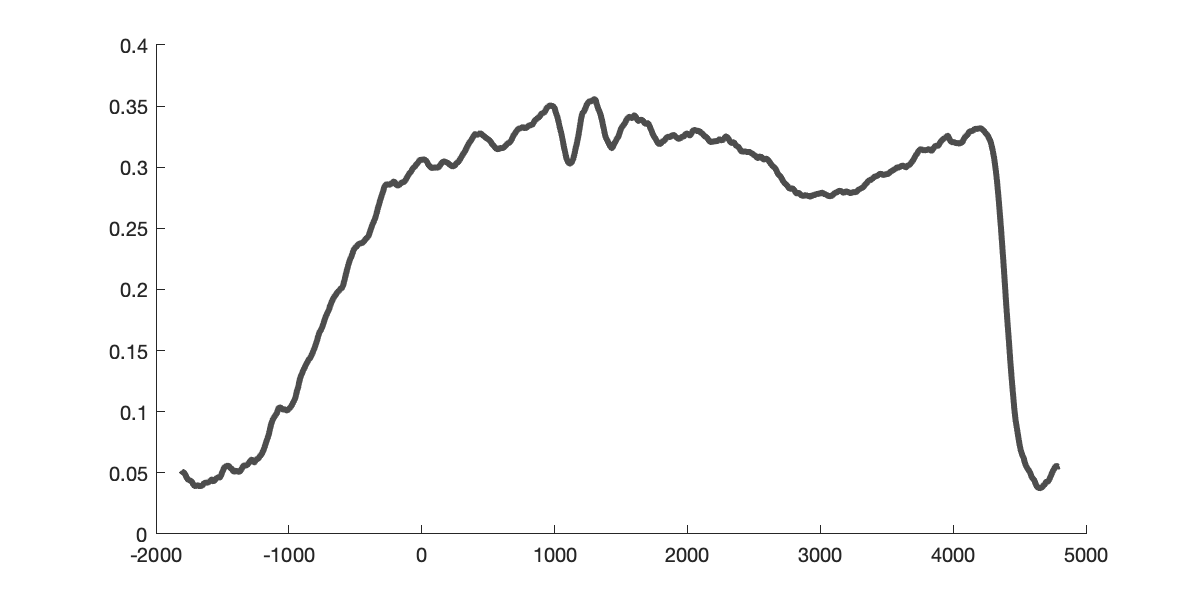

%% FIG: 20 Hz ITPC time series, average across all trials, check individual derivative 0 before T1 
% December 13, 2021 sanity check 

% setup 
sampling = 1:10:7001;
freq = 20; 
vals = squeeze(A.all.subject(freq,:,:));  % frequency x time x subject (from avg sessions)
groupVals = squeeze(mean(vals,2)); % average across subject 
groupVals = groupVals(sampling); 
t = p.t(sampling); 

% figure 
figure
set(gcf,'Position',[100 100 600 300])
hold on 
plot(t, groupVals,'LineWidth',3,'Color',[0.3 0.3 0.3])

for i = 1:10
    plot(t,vals(t,i),'LineWidth',1)
end

Index in position 1 is invalid. Array indices must be positive integers or logical values.

meg_figureStyle
for i = 1:numel(p.eventTimes)
    xline(p.eventTimes(i),'Color',[0.5 0.5 0.5],'LineWidth',1)
end
xlabel('Time (ms)')
ylabel('ITPC')
title('Group raw ITPC time series')
figTitle = 'GroupRawITPC-ts'; 

% December 10 timing check 
xlim([-100 1100])
% [~,afterCushion] = min(groupVals(0+200:20+200)); 
% xline(afterCushion*10) 
% [~,beforeCushion] = max(groupVals(90+200:100+200)); 
% xline((100-beforeCushion)*10) 

if saveFigs 
    saveas(gcf,sprintf('%s.svg', figTitle)) 
end


%% FIG: 20 Hz ITPC by jitter
% run kt_ITPCbyITI.m to load and prepare data, variableOI =
% groupITP_ITI.group

% setup 
sampling = 1:10:7001;

% figure 
figure
set(gcf,'Position',[100 100 800 400])

hold on
for iField = 1:numel(fields)
    pLine(iField) = plot(toi(sampling),groupITPC_ITI.group.(fields{iField})(foi,sampling),'Color',[p.cueColors(iField,:) 0.8],'LineWidth',2,...
        'DisplayName',fields{iField},'LineWidth',2);
    pause(1)
end
% xlim([toi(1) toi(end)])
xlim([-1600 2350])
ylim([0 0.4])
yticks(0:0.1:0.4)
set(gca,'TickDir','out');
ax = gca;
ax.LineWidth = 1.5;
ax.XColor = 'black';
ax.YColor = 'black';
ax.FontSize = 12;
xlabel('Time (ms)')
ylabel('ITPC')
legend([pLine(1) pLine(2) pLine(3) pLine(4) pLine(5) pLine(6)],fields)
legend('Location','northeastoutside','NumColumns',1)
legend('boxoff')
box off
for iEv = 1:numel(p.eventTimes) % plot event times
    xline(p.eventTimes(iEv),'k','LineWidth',1,'HandleVisibility','off');
end
for iEv = 1:numel(fields) % plot ITI times
    ITIs = [-500,-700,-900,-1100,-1300,-1500];
    xline(ITIs(iEv),'-','Color',p.cueColors(iEv,:),'LineWidth',1,'HandleVisibility','off');
end
figTitle = 'ITPCbyITI'; 
meg_figureStyle
% yline(0,'k','LineWidth',0.5)
if saveFigs
    saveas(gcf,sprintf('%s.svg', figTitle)) 
end

%% 20 Hz ITPC point wise ttest
% freq = 20; 
% t = p.t; 
% vals_cueT1 = squeeze(A.cueT1.normSubject(freq,:,:)); 
% vals_cueT2 = squeeze(A.cueT2.normSubject(freq,:,:)); 
% 
% groupVals_cueT1 = mean(vals_cueT1,2); 
% groupVals_cueT2 = mean(vals_cueT2,2); 
% 
% figure
% hold on 
% set(gcf,'Position',[100 100 600 300])
% plot(t, groupVals_cueT1,'LineWidth',3,'Color',p.cueColors(1,:))
% plot(t, groupVals_cueT2,'LineWidth',3,'Color',p.cueColors(2,:))
% 
% for i = 1:length(t)
%     if sum(isnan(vals_cueT1(i,:)))==0 && sum(isnan(vals_cueT2(i,:)))==0 
%         [h(i),pVal(i)] = ttest(vals_cueT1(i,:),vals_cueT2(i,:)); 
%     end
% end
% hSig = find(h); 
% 
% for i = 1:numel(hSig) % lines for significance 
%     xline(t(hSig(i)),'Color',[0.8 0.8 0.8],'LineWidth',1)
% end
% 
% for i = 1:numel(p.eventTimes) % event time lines 
%     xline(p.eventTimes(i),'Color',[0.5 0.5 0.5],'LineWidth',1)
% end
% 
% meg_figureStyle
% xlabel('Time (ms)') 
% ylabel('ITPC')
% title('Normalized ITPC time series by cue')
% figTitle = 'GroupNormITPC-cue-ts'; 
% print(figTitle,'-dsvg')





